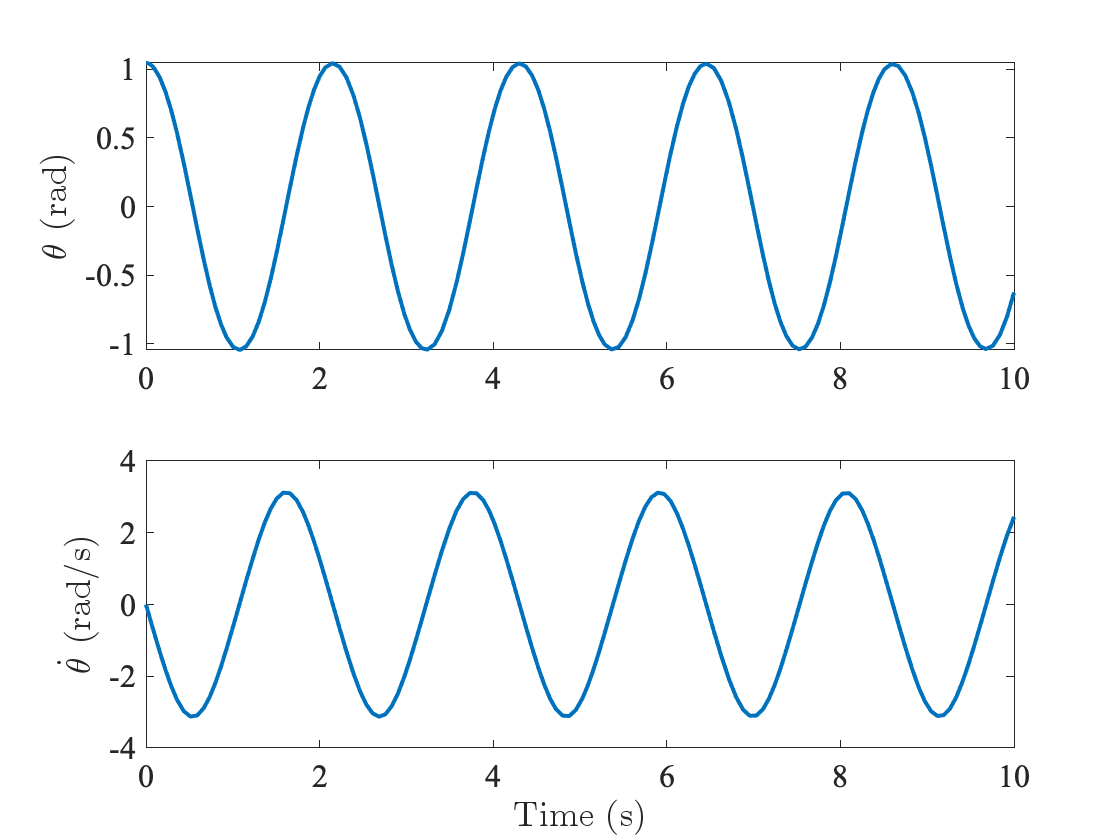

%run solution to get plots:
simplePendulumHWExample();

Then save this script by going to Save>Export to PDF in the Live Editor.  Alternatively, export the function and graphics individually as PDFs (or other image formats) and combine them yourself.

function res = simplePendulumHWExample()
% simplePendulumHWExample numerically integrates the equations of motion of
% a simple pendulum and plots the results. Note that you can also split
% this same code into two files - the integrator function and a script to
% do the integration and make the plots.
%
% A. Student.  HW #0

g = 9.81;   %m/s^2  acceleration due to graivty
l = 1;      %m      length of pendulum arm
m = 1;      %kg     mass of pendulum bob

tin = [0,10];    %s      integration time span
y0 = [pi/3,0];  %rad,rad/s    initial conditions


    %simple pendulum ODE function
    %always use nested functions or anonymous functions
    %if defining integration function in the same file as 
    %the integrator call
    %when time is not needed by the integration function
    %replace the input variable with ~
    function dy = simplePendulumODE(~,y)
        dy = [y(2);...
            -g/l*sin(y(1))];
    end

[t,res] = ode45(@simplePendulumODE,tin,y0);

%plot results
%using subplots, but you can make two figures
%never put two different measurements (i.e., angle and angle rate of
%change) on the same axis
figure(1)
subplot(2,1,1) 
plot(t,res(:,1),'LineWidth',2) %plot theta; bumping up line width for legibility
set(gca,'FontName','Times','FontSize',16) %just to make things more legible
ylabel('$\theta$ (rad)','Interpreter','Latex') %all axes MUST be labeled

subplot(2,1,2)
plot(t,res(:,2),'LineWidth',2) %plot theta rate of change
set(gca,'FontName','Times','FontSize',16)
xlabel('Time (s)','Interpreter','Latex')
ylabel('$\dot\theta$ (rad/s)','Interpreter','Latex')

end
